# Diffusion Monte Carlo

See write-up for explanation and analysis of the following calculations.

## Set Pseudorandom Number Generator Seed

rng(737308, 'twister');  % Set seed for Mersenne Twister

## Initial Test

% Unguided DMC for one-dimensional harmonic oscillator, M = 100
D = 1/2;                   % Diffusion constant for electron
dims = 1;                  % Dimensions of the problem
V = @(x) x^2/2;            % One-dimensional harmonic oscillator potential
M = 100;                   % Initial number of walkers
xs0 = (rand(dims,M)-0.5);  % Starting positions for walkers
E00 = 1;                   % Initial energy estimate
dt = 0.01;                 % Time step
steps = 1000;              % Total number of steps for simulation
bSteps = 20;               % Energy estimate E0 adjusted every bSteps steps
a = 0.01;                  % Proportionality factor
[E0, xs] = DMC(D,dims,V,xs0,E00,dt,M,steps,bSteps,a);  % Run simulation
E0                                                     % Print E0

E0 =    0.506064898600324


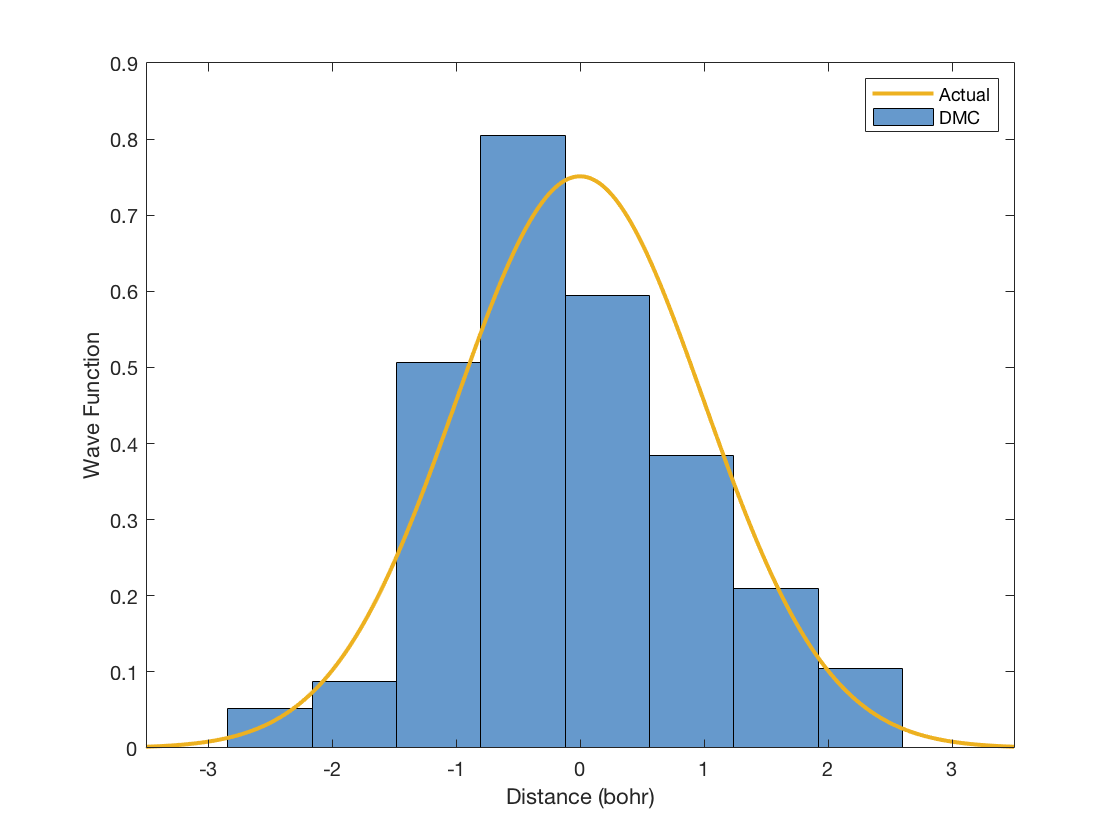

p0 = @(x) pi^(-1/4)*exp(-0.5*x.^2);      % True ground state wave function
plotDMC(p0,xs,10,[-1,1]*3.5,false,true)  % Generate plot (see file plotDMC.m)

% Guided DMC for one-dimensional harmonic oscillator, M = 100
D = 1/2;                            % Diffusion constant for electron
dims = 1;                           % Dimensions of the problem
V = @(x) x^2/2;                     % 1D harmonic oscillator potential
b = 0.4;                            % Parameter for trial wave function
PT = @(x) exp(-b*x^2);              % Trial wave function
EL = @(x) -D*(4*b^2*x^2-2*b)+V(x);  % Local energy
F = @(x) -4*b*x;                    % Quantum force
E00 = 1;                            % Initial energy estimate
dt = 0.01;                          % Time step
M = 100;                            % Initial number of walkers
steps = 1000;                       % Number of Monte Carlo steps
bSteps = 20;                        % Number of steps to adjust energy E after
a = 0.01;                           % Proportionality factor d
[E0, xs] = DMCguided(D,dims,PT,EL,F,E00,dt,M,steps,bSteps,a);  % Run simulation
E0                                                             % Print E0

E0 =    0.499275606776310


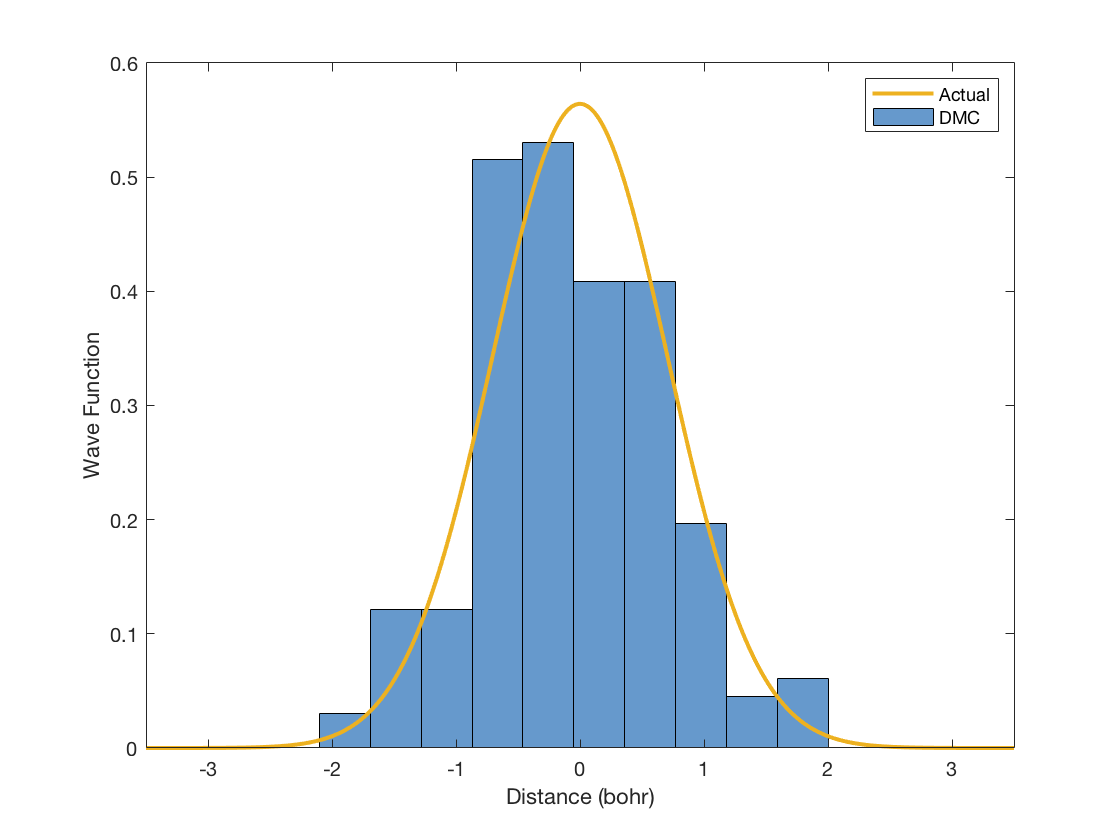

p0 = @(x) pi^(-1/4)*exp(-0.5*x.^2);   % True ground state wave function
plotDMC(@(x) p0(x)^2,xs,10,[-1,1]*3.5,true,true)  % Generate plot (see file plotDMC.m)

% Guided DMC for one-dimensional harmonic oscillator, M = 1000
D = 1/2;                            % Diffusion constant for electron
dims = 1;                           % Dimensions of the problem
V = @(x) x^2/2;                     % 1D harmonic oscillator potential
b = 0.4;                            % Parameter for trial wave function
PT = @(x) exp(-b*x^2);              % Trial wave function
EL = @(x) -D*(4*b^2*x^2-2*b)+V(x);  % Local energy
F = @(x) -4*b*x;                    % Quantum force
E00 = 1;                            % Initial energy estimate
dt = 0.01;                          % Time step
M = 1000;                           % Initial number of walkers
steps = 1000;                       % Number of Monte Carlo steps
bSteps = 20;                        % Number of steps to adjust energy E after
a = 0.01;                           % Proportionality factor d
[E0, xs] = DMCguided(D,dims,PT,EL,F,E00,dt,M,steps,bSteps,a);  % Run simulation
E0                                                             % Print E0

E0 =    0.506748132009927


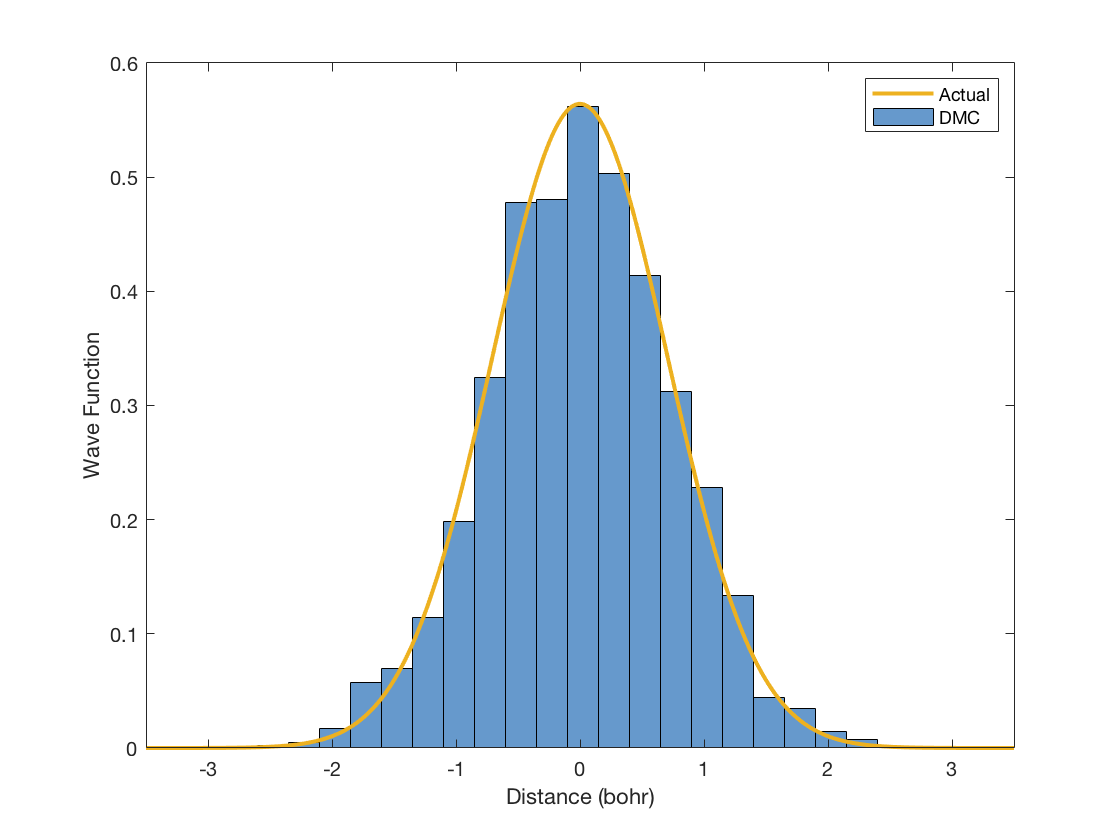

p0 = @(x) pi^(-1/4)*exp(-0.5*x.^2);   % True ground state wave function
plotDMC(@(x) p0(x)^2,xs,20,[-1,1]*3.5,true,true)  % Generate plot (see file plotDMC.m)

## Statistical Error

% Unguided DMC for one-dimensional harmonic oscillator
D = 1/2;                   % Diffusion constant for electron
dims = 1;                  % Dimensions of the problem
V = @(x) x^2/2;            % One-dimensional harmonic oscillator potential
M = 100;                   % Initial number of walkers
xs0 = (rand(dims,M)-0.5);  % Starting positions for walkers
E00 = 1;                   % Initial energy estimate
dt = 0.01;                 % Time step
steps = 1000;              % Total number of steps for simulation
bSteps = 20;               % Energy estimate E0 adjusted every bSteps steps
a = 0.01;                  % Proportionality factor
N = 100;                   % Number of samples
samples = zeros(N,1);      % Initialize samples array
tic;
parfor i = 1:N             % Parallelize to increase efficiency
    samples(i) = DMC(D,dims,V,xs0,E00,dt,M,steps,bSteps,a);
end
toc;

Elapsed time is 46.879044 seconds.


mean(samples)                       % Calculate mean

ans =    0.501782707723834


std(samples)                        % Calculate standard deviation

ans =    0.043179421240215


% Guided DMC for one-dimensional harmonic oscillator, b = 0.2
D = 1/2;                            % Diffusion constant for electron
dims = 1;                           % Dimensions of the problem
V = @(x) x^2/2;                     % 1D harmonic oscillator potential
b = 0.2;                            % Parameter for trial wave function
PT = @(x) exp(-b*x^2);              % Trial wave function
EL = @(x) -D*(4*b^2*x^2-2*b)+V(x);  % Local energy
F = @(x) -4*b*x;                    % Quantum force
E00 = 1;                            % Initial energy estimate
dt = 0.01;                          % Time step
M = 100;                            % Initial number of walkers
steps = 1000;                       % Number of Monte Carlo steps
bSteps = 20;                        % Number of steps to adjust energy E after
a = 0.01;                           % Proportionality factor
N = 100;                            % Number of samples
samples = zeros(N,1);               % Initialize samples array
tic;
parfor i = 1:N                      % Parallelize to increase efficiency
    samples(i) = DMCguided(D,dims,PT,EL,F,E00,dt,M,steps,bSteps,a);
end
toc;

Elapsed time is 65.124740 seconds.


mean(samples)                       % Calculate mean

ans =    0.502253507794219


std(samples)                        % Calculate standard deviation

ans =    0.038588605128098


% Guided DMC for one-dimensional harmonic oscillator, b = 0.4
D = 1/2;                            % Diffusion constant for electron
dims = 1;                           % Dimensions of the problem
V = @(x) x^2/2;                     % 1D harmonic oscillator potential
b = 0.4;                            % Parameter for trial wave function
PT = @(x) exp(-b*x^2);              % Trial wave function
EL = @(x) -D*(4*b^2*x^2-2*b)+V(x);  % Local energy
F = @(x) -4*b*x;                    % Quantum force
E00 = 1;                            % Initial energy estimate
dt = 0.01;                          % Time step
M = 100;                            % Initial number of walkers
steps = 1000;                       % Number of Monte Carlo steps
bSteps = 20;                        % Number of steps to adjust energy E after
a = 0.01;                           % Proportionality factor
N = 100;                            % Number of samples
samples = zeros(N,1);               % Initialize samples array
tic;
parfor i = 1:N                      % Parallelize to increase efficiency
    samples(i) = DMCguided(D,dims,PT,EL,F,E00,dt,M,steps,bSteps,a);
end
toc;

Elapsed time is 65.696972 seconds.


mean(samples)                       % Calculate mean

ans =    0.498771409489075


std(samples)                        % Calculate standard deviation

ans =    0.018907080387139


% Guided DMC for one-dimensional harmonic oscillator, b = 0.6
D = 1/2;                            % Diffusion constant for electron
dims = 1;                           % Dimensions of the problem
V = @(x) x^2/2;                     % 1D harmonic oscillator potential
b = 0.6;                            % Parameter for trial wave function
PT = @(x) exp(-b*x^2);              % Trial wave function
EL = @(x) -D*(4*b^2*x^2-2*b)+V(x);  % Local energy
F = @(x) -4*b*x;                    % Quantum force
E00 = 1;                            % Initial energy estimate
dt = 0.01;                          % Time step
M = 100;                            % Initial number of walkers
steps = 1000;                       % Number of Monte Carlo steps
bSteps = 20;                        % Number of steps to adjust energy E after
a = 0.01;                           % Proportionality factor
N = 100;                            % Number of samples
samples = zeros(N,1);               % Initialize samples array
tic;
parfor i = 1:N                      % Parallelize to increase efficiency
    samples(i) = DMCguided(D,dims,PT,EL,F,E00,dt,M,steps,bSteps,a);
end
toc;

Elapsed time is 66.873425 seconds.


mean(samples)                       % Calculate mean

ans =    0.497338370091220


std(samples)                        % Calculate standard deviation

ans =    0.021972548309742


% Guided DMC for one-dimensional harmonic oscillator, b = 0.8
D = 1/2;                            % Diffusion constant for electron
dims = 1;                           % Dimensions of the problem
V = @(x) x^2/2;                     % 1D harmonic oscillator potential
b = 0.8;                            % Parameter for trial wave function
PT = @(x) exp(-b*x^2);              % Trial wave function
EL = @(x) -D*(4*b^2*x^2-2*b)+V(x);  % Local energy
F = @(x) -4*b*x;                    % Quantum force
E00 = 1;                            % Initial energy estimate
dt = 0.01;                          % Time step
M = 100;                            % Initial number of walkers
steps = 1000;                       % Number of Monte Carlo steps
bSteps = 20;                        % Number of steps to adjust energy E after
a = 0.01;                           % Proportionality factor
N = 100;                            % Number of samples
samples = zeros(N,1);               % Initialize samples array
tic;
parfor i = 1:N                      % Parallelize to increase efficiency
    samples(i) = DMCguided(D,dims,PT,EL,F,E00,dt,M,steps,bSteps,a);
end
toc;

Elapsed time is 69.615749 seconds.


mean(samples)                       % Calculate mean

ans =    0.497864016356213


std(samples)                        % Calculate standard deviation

ans =    0.043797324105655


% Guided DMC for one-dimensional harmonic oscillator, b = 1
D = 1/2;                            % Diffusion constant for electron
dims = 1;                           % Dimensions of the problem
V = @(x) x^2/2;                     % 1D harmonic oscillator potential
b = 1;                              % Parameter for trial wave function
PT = @(x) exp(-b*x^2);              % Trial wave function
EL = @(x) -D*(4*b^2*x^2-2*b)+V(x);  % Local energy
F = @(x) -4*b*x;                    % Quantum force
E00 = 1;                            % Initial energy estimate
dt = 0.01;                          % Time step
M = 100;                            % Initial number of walkers
steps = 1000;                       % Number of Monte Carlo steps
bSteps = 20;                        % Number of steps to adjust energy E after
a = 0.01;                           % Proportionality factor
N = 100;                            % Number of samples
samples = zeros(N,1);               % Initialize samples array
tic;
parfor i = 1:N                      % Parallelize to increase efficiency
    samples(i) = DMCguided(D,dims,PT,EL,F,E00,dt,M,steps,bSteps,a);
end
toc;

Elapsed time is 66.488571 seconds.


mean(samples)                       % Calculate mean

ans =    0.506843731414573


std(samples)                        % Calculate standard deviation

ans =    0.064553350526165


## Estimates and Errors

% Unguided DMC for one-dimensional harmonic oscillator
D = 1/2;                   % Diffusion constant for electron
dims = 1;                  % Dimensions of the problem
V = @(x) x^2/2;            % One-dimensional harmonic oscillator potential
M = 100;                   % Initial number of walkers
xs0 = (rand(dims,M)-0.5);  % Starting positions for walkers
E00 = 1;                   % Initial energy estimate
dt = 0.01;                 % Time step
steps = 1000;              % Total number of steps for simulation
bSteps = 20;               % Energy estimate E0 adjusted every bSteps steps
a = 0.01;                  % Proportionality factor
N = 100;                   % Number of samples
samples = zeros(N,1);      % Initialize samples array
tic;
parfor i = 1:N             % Parallelize to increase efficiency
    samples(i) = DMC(D,dims,V,xs0,E00,dt,M,steps,bSteps,a);
end
toc;

Elapsed time is 49.074143 seconds.


mean(samples)                       % Calculate mean

ans =    0.501817173712552


std(samples)                        % Calculate standard deviation

ans =    0.047275792970990


% Guided DMC for one-dimensional harmonic oscillator
D = 1/2;                            % Diffusion constant for electron
dims = 1;                           % Dimensions of the problem
V = @(x) x^2/2;                     % 1D harmonic oscillator potential
b = 0.4;                            % Parameter for trial wave function
PT = @(x) exp(-b*x^2);              % Trial wave function
EL = @(x) -D*(4*b^2*x^2-2*b)+V(x);  % Local energy
F = @(x) -4*b*x;                    % Quantum force
E00 = 1;                            % Initial energy estimate
dt = 0.01;                          % Time step
M = 100;                            % Initial number of walkers
steps = 1000;                       % Number of Monte Carlo steps
bSteps = 20;                        % Number of steps to adjust energy E after
a = 0.01;                           % Proportionality factor
N = 100;                            % Number of samples
samples = zeros(N,1);               % Initialize samples array
tic;
parfor i = 1:N                      % Parallelize to increase efficiency
    samples(i) = DMCguided(D,dims,PT,EL,F,E00,dt,M,steps,bSteps,a);
end
toc;

Elapsed time is 69.608528 seconds.


mean(samples)                       % Calculate mean

ans =    0.501459349989904


std(samples)                        % Calculate standard deviation

ans =    0.017900241253321


% Unguided DMC for hydrogen
D = 1/2;                   % Diffusion constant for electron
dims = 3;                  % Dimensions of the problem
V = @(r) -1/norm(r);       % Hydrogen potential
M = 100;                   % Initial number of walkers
rs0 = (rand(dims,M)-0.5);  % Starting positions for walkers
E00 = -1;                  % Initial energy estimate
dt = 0.01;                 % Time step
steps = 1000;              % Total number of steps for simulation
bSteps = 20;               % Energy estimate E0 adjusted every bSteps steps
a = 0.01;                  % Proportionality factor
N = 100;                   % Number of samples
samples = zeros(N,1);      % Initialize samples array
tic;
parfor i = 1:N             % Parallelize to increase efficiency
    samples(i) = DMC(D,dims,V,rs0,E00,dt,M,steps,bSteps,a);
end
toc;

Elapsed time is 34.030544 seconds.


mean(samples)                       % Calculate mean

ans =   -0.482050110812274


std(samples)                        % Calculate standard deviation

ans =    0.102219300708934


% Guided DMC for hydrogen
D = 1/2;                              % Diffusion constant for electron
dims = 3;                             % Dimensions of the problem
V = @(r) -1/norm(r);                  % 1D harmonic oscillator potential
b = 0.9;                              % Parameter for trial wave function
PT = @(r) exp(-b*norm(r));            % Trial wave function
EL = @(r) -D*(b^2-2*b/norm(r))+V(r);  % Local energy
F = @(r) -2*b*r/norm(r);              % Quantum force
E00 = -1;                             % Initial energy estimate
dt = 0.01;                            % Time step
M = 100;                              % Initial number of walkers
steps = 1000;                         % Number of Monte Carlo steps
bSteps = 20;                          % Number of steps to adjust energy E after
a = 0.01;                             % Proportionality factor
N = 100;                              % Number of samples
samples = zeros(N,1);                 % Initialize samples array
tic;
parfor i = 1:N                        % Parallelize to increase efficiency
    samples(i) = DMCguided(D,dims,PT,EL,F,E00,dt,M,steps,bSteps,a);
end
toc;

Elapsed time is 32.298507 seconds.


mean(samples)                         % Calculate mean

ans =   -0.497832692184219


std(samples)                          % Calculate standard deviation

ans =    0.024836286495581


% Unguided DMC for helium
D = 1/2;                   % Diffusion constant for electron
dims = 6;                  % 6 dimensions (3 spatial * 2 electrons)
V = @(r) -2/norm(r(1:3))-2/norm(r(4:6))+1/norm(r(1:3)-r(4:6));  % Helium potential
M = 100;                   % Initial number of walkers
rs0 = (rand(dims,M)-0.5);  % Starting positions for walkers
E00 = -3;                  % Initial energy estimate
dt = 0.01;                 % Time step
steps = 1000;              % Total number of steps for simulation
bSteps = 20;               % Energy estimate E0 adjusted every bSteps steps
a = 0.01;                  % Proportionality factor
N = 100;                   % Number of samples
samples = zeros(N,1);      % Initialize samples array
tic;
parfor i = 1:N             % Parallelize to increase efficiency
    samples(i) = DMC(D,dims,V,rs0,E00,dt,M,steps,bSteps,a);
end
toc;

Elapsed time is 42.655734 seconds.


mean(samples)                       % Calculate mean

ans =   -2.443734975492376


std(samples)                        % Calculate standard deviation

ans =    0.578993093631284


% Guided DMC for helium
D = 1/2;                              % Diffusion constant for electron
dims = 6;                             % 6 dimensions (3 spatial * 2 electrons)
V = @(R) -2/norm(R(1:3))-2/norm(R(4:6))+1/norm(R(1:3)-R(4:6));  % Helium potential
b = 2;                                % Parameter for trial wave function
PT = @(R) exp(-b*(norm(R(1:3))+norm(R(4:6))));                  % Trial wave function
EL = @(R) -2*D*(b^2-b*(1/norm(R(1:3))+1/norm(R(4:6))))+V(R);    % Local energy
F = @(R) -2*b*[R(1:3)/norm(R(1:3));R(4:6)/norm(R(4:6))];        % Quantum force
E00 = -3;                             % Initial energy estimate
dt = 0.01;                            % Time step
M = 100;                              % Initial number of walkers
steps = 1000;                         % Number of Monte Carlo steps
bSteps = 20;                          % Number of steps to adjust energy E after
a = 0.01;                             % Proportionality factor
N = 100;                              % Number of samples
samples = zeros(N,1);                 % Initialize samples array
tic;
parfor i = 1:N                        % Parallelize to increase efficiency
    samples(i) = DMCguided(D,dims,PT,EL,F,E00,dt,M,steps,bSteps,a);
end
toc;

Elapsed time is 69.324211 seconds.


mean(samples)                         % Calculate mean

ans =   -2.932350933260267


std(samples)                          % Calculate standard deviation

ans =    0.058123143776993


% Guided DMC for helium, M = 1000
D = 1/2;                              % Diffusion constant for electron
dims = 6;                             % 6 dimensions (3 spatial * 2 electrons)
V = @(R) -2/norm(R(1:3))-2/norm(R(4:6))+1/norm(R(1:3)-R(4:6));  % Helium potential
b = 2;                                % Parameter for trial wave function
PT = @(R) exp(-b*(norm(R(1:3))+norm(R(4:6))));                  % Trial wave function
EL = @(R) -2*D*(b^2-b*(1/norm(R(1:3))+1/norm(R(4:6))))+V(R);    % Local energy
F = @(R) -2*b*[R(1:3)/norm(R(1:3));R(4:6)/norm(R(4:6))];        % Quantum force
E00 = -3;                             % Initial energy estimate
dt = 0.01;                            % Time step
M = 1000;                             % Initial number of walkers
steps = 1000;                         % Number of Monte Carlo steps
bSteps = 20;                          % Number of steps to adjust energy E after
a = 0.01;                             % Proportionality factor
N = 10;                               % Number of samples
samples = zeros(N,1);                 % Initialize samples array
tic;
parfor i = 1:N                        % Parallelize to increase efficiency
    samples(i) = DMCguided(D,dims,PT,EL,F,E00,dt,M,steps,bSteps,a);
end
toc;

Elapsed time is 77.756286 seconds.


mean(samples)                         % Calculate mean

ans =   -2.924733310023869


std(samples)                          % Calculate standard deviation

ans =    0.023310555996592


## Plotting Hydrogen and Helium

% Guided DMC for hydrogen, M = 10000
D = 1/2;                              % Diffusion constant for electron
dims = 3;                             % Dimensions of the problem
V = @(r) -1/norm(r);                  % 1D harmonic oscillator potential
b = 0.9;                              % Parameter for trial wave function
PT = @(r) exp(-b*norm(r));            % Trial wave function
EL = @(r) -D*(b^2-2*b/norm(r))+V(r);  % Local energy
F = @(r) -2*b*r/norm(r);              % Quantum force
E00 = -1;                             % Initial energy estimate
dt = 0.01;                            % Time step
M = 10000;                            % Initial number of walkers
steps = 1000;                         % Number of Monte Carlo steps
bSteps = 20;                          % Number of steps to adjust energy E after
a = 0.01;                             % Proportionality factor
tic; [E0, rs] = DMCguided(D,dims,PT,EL,F,E00,dt,M,steps,bSteps,a); toc;

Elapsed time is 87.531046 seconds.


E0

E0 =   -0.502688171869943


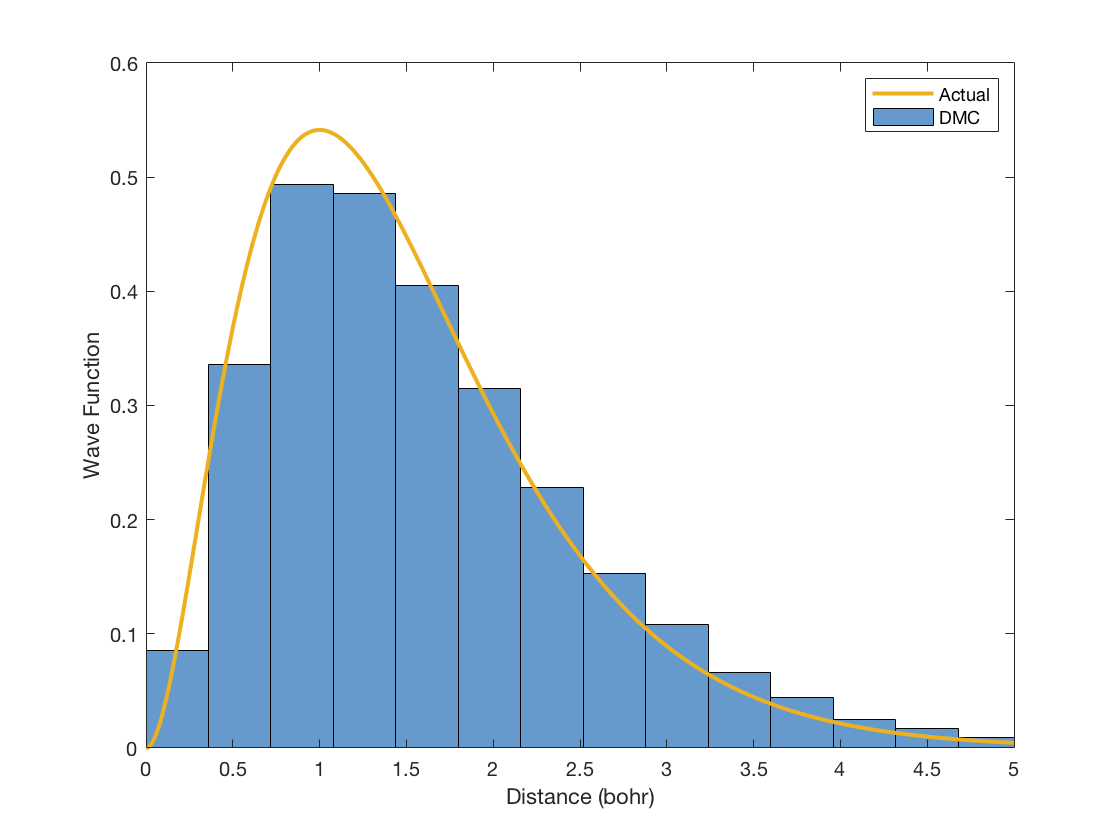

rads = sqrt(sum(rs.^2));                    % Convert points to radial distances
p2R = @(r) 4*pi*r^2*(pi^(-1/2)*exp(-r))^2;  % Radial probability distribution
plotDMC(p2R,rads,20,[0,1]*5,true,true)      % Generate plot (see file plotDMC.m)

% Guided DMC for helium, M = 10000
D = 1/2;                              % Diffusion constant for electron
dims = 6;                             % 6 dimensions (3 spatial * 2 electrons)
V = @(R) -2/norm(R(1:3))-2/norm(R(4:6))+1/norm(R(1:3)-R(4:6));  % Helium potential
b = 2;                                % Parameter for trial wave function
PT = @(R) exp(-b*(norm(R(1:3))+norm(R(4:6))));                  % Trial wave function
EL = @(R) -2*D*(b^2-b*(1/norm(R(1:3))+1/norm(R(4:6))))+V(R);    % Local energy
F = @(R) -2*b*[R(1:3)/norm(R(1:3));R(4:6)/norm(R(4:6))];        % Quantum force
E00 = -3;                             % Initial energy estimate
dt = 0.01;                            % Time step
M = 10000;                            % Initial number of walkers
steps = 1000;                         % Number of Monte Carlo steps
bSteps = 20;                          % Number of steps to adjust energy E after
a = 0.01;                             % Proportionality factor
tic; [E0, Rs] = DMCguided(D,dims,PT,EL,F,E00,dt,M,steps,bSteps,a); toc;

Elapsed time is 206.136470 seconds.


E0

E0 =   -2.903690007761713


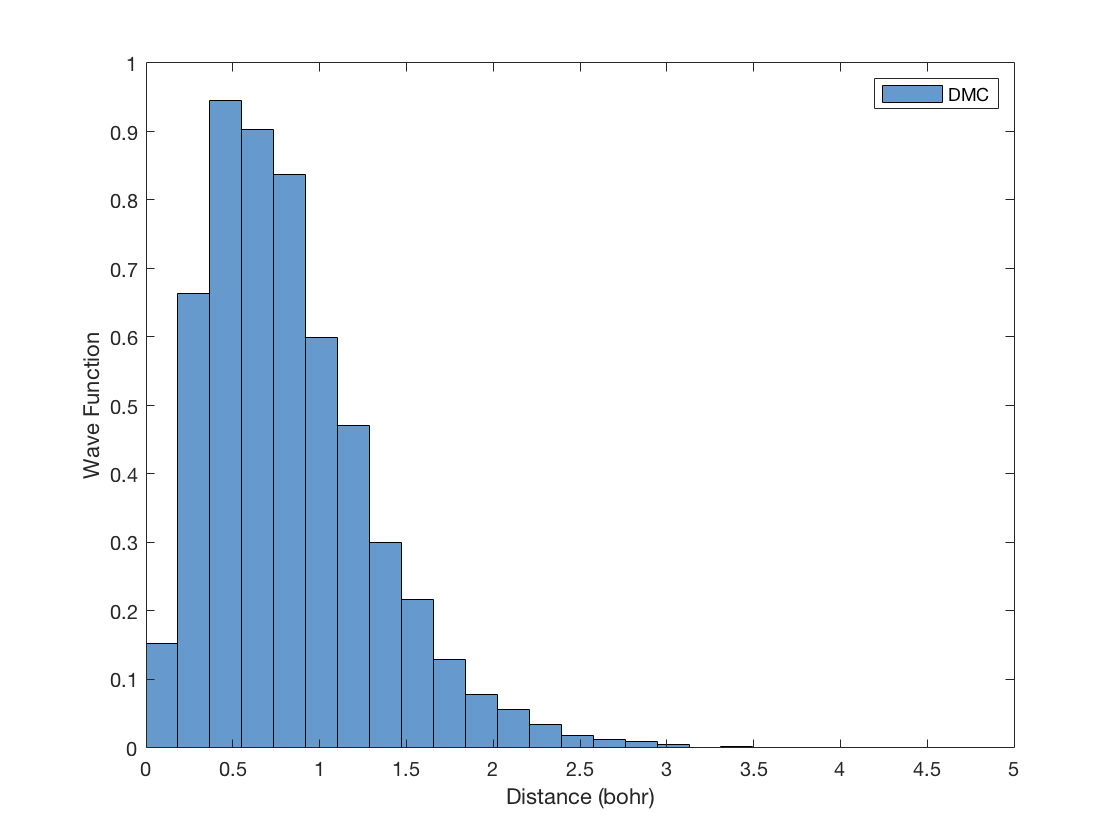

rad1s = sqrt(sum(Rs(1:3,:).^2));      % Calculate radial distances for electron 1
rad2s = sqrt(sum(Rs(4:6,:).^2));      % Calculate radial distances for electron 2
plotDMC(@(r)0,rad1s,20,[0,1]*5,true,false)  % Generate plot (see file plotDMC.m)